clc; clear;

Read image

image= imread('Y18.jpg');

Change to binary image

bw = im2bw(image,0.60);

Plot original image

subplot(1,3,1);
imshow(image);
label = bwlabel(bw);

Measure solidity and area of tumor

stats = regionprops(label, 'Solidity', 'Area');
density = [stats.Solidity];
area = [stats.Area];

Filter out areas of low density

denseArea = density > 0.25;

Findest largest occurence of acceptable density

largestArea = max(area(denseArea));

Determine tumor to be outlined

tumorOutline = find(area == largestArea);
finalTumor = ismember(label, tumorOutline);
se = strel('diamond',5)

se = strel is a diamond shaped structuring element with properties:

      Neighborhood: [11×11 logical]
    Dimensionality: 2


Dilate final tumor

finalTumor = imdilate(finalTumor,se);

Plot just outlined tumor

subplot(1,2,2);
imshow(finalTumor,[]);

Remove holes from dilated tumor

[B,L]= bwboundaries(finalTumor,'noholes');

Outline tumor

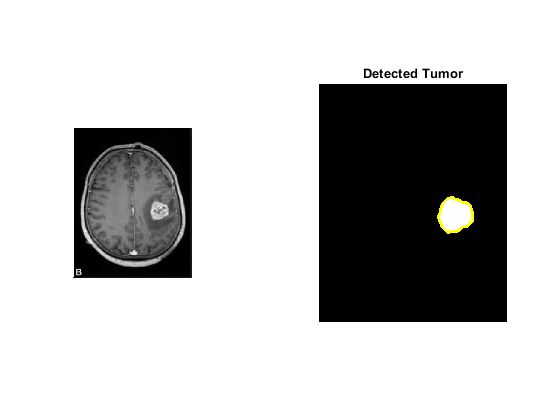

hold on
for i = 1:length(B)
    plot(B{i}(:,2),B{i}(:,1),'y','linewidth',2);
end
title('Detected Tumor');
hold off

Create another variable of original image

Image= image;

Convert image to gray-scale

Image = rgb2gray(Image);

Sobel edge dectection

[~,threshold] = edge(Image, 'sobel');
fudgeFactor = 0.5;
Imageedge = edge(Image,'sobel', threshold*fudgeFactor);

Dilate image

se90 = strel('line',3,90);
se0 = strel('line',3,0);
Imagedilated = imdilate(Imageedge,[se90,se0]);

Fill gaps in the tumor

Imagefilled = imfill(Imagedilated,'holes');

Clear borders

Imagenobord = imclearborder(Imagefilled,4);

Smooth tumor edges

seD = strel('diamond',1);

Create final image

Imagefinal = imerode(Imagenobord,seD);
Imagefinal = imerode(Imagefinal,seD);

Find area of the brain and tumors(white pixels)

tumorArea = nnz(finalTumor);
brainArea = nnz(Image);

Calculate percentage covered by tumor

fprintf('Percentage of Brain Covered by Tumor: %0.3f',tumorArea/brainArea*100);

Percentage of Brain Covered by Tumor: 2.635